Projeto 1 de Topicos em Engenharia Mecatronica

--------------------------------------------------------------------- 

Nome: Gabriel Evangelista Correia   RA: 250320

---------------------------------------------------------------------

Parte 0:

---------------------------------------------------------------------

clc ; clear; close all force;
RA = '250320';
d = digitosRA(RA)

d =      2     5     0     3     2     0


Utilizando a funçao digitosRA, transformamos a string RA em um numero e com isso alocamos cada digito desse numero em uma posiçao do vetor d. Esse vetor será utlizado nos cálculos seguintes.

[L,Izz,M0,b,h] = dados_problema(d)

L = 20

Izz = 2.9160e-05

M0 = 25000

b = 0.0600

h = 0.1800

Aplicando a funçao dados_problema e passando como parametro o vetor "d" obtido no item acima, obtemos o comprimento da viga L, o segundo momento de área Izz e o momento fletor M0:

---------------------------------------------------------------------

Parte 1:

---------------------------------------------------------------------

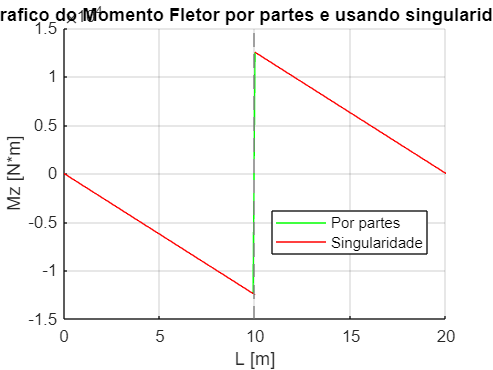

E = 210e9; %Pa
rho = 7850; %kg/m^3
x = 0:0.1:L;
P = M0/L;

figure;
hold on;
grid on;

%Primeiro Plot
Mz = momento(P,L,M0);
plot(x,Mz,'g');
ylabel('Mz [N*m]');
xlabel('L [m]');


%Segundo Plot
Mz = @(x) P*L - M0 - P*x + M0*sing((x-L/2),0);
fplot(Mz, [0 L], "r");
legend('Por partes', 'Singularidade', 'Location','best');
title('Grafico do Momento Fletor por partes e usando singularidade');
hold off

Como nota-se pelo gráfico os resultados gerados pela curva gerada pela equaçao por partes e por singularidade sao praticamente iguais.

Mz_obtem_maximo = @(x) -1*(P*L - M0 - P*x + M0*sing((x-L/2),0)); 
x_max = fminbnd(Mz_obtem_maximo,0,20)

x_max = 10.0000

Para obter o x maximo, invertemos o sinal da funcao Mz e aplicamos a ela a funçao de encontrar o valor minimo de x. Com isso, assumimos que esse valor de x equivale ao valor maximo da funçao Mz.

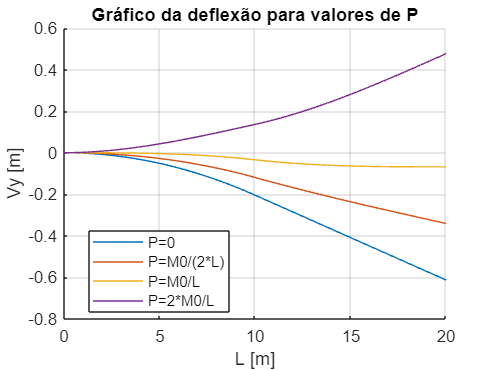

figure;
hold on;
grid on;

%Primeiro Plot
P=0;
Vy = @(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
fplot(Vy,[0 L]);
ylabel('Vy [m]');
xlabel('L [m]');

%Segundo Plot 
P = M0/(2*L);
Vy = @(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
fplot(Vy,[0 L]);
ylabel('Vy [m]');
xlabel('L [m]');

%Terceiro Plot
P=M0/L;
Vy = @(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));;
fplot(Vy,[0 L]);
ylabel('Vy [m]');
xlabel('L [m]');

%Quarto Plot
P=2*M0/L;
Vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
fplot(Vy,[0 L]);
ylabel('Vy [m]');
xlabel('L [m]');

legend('P=0','P=M0/(2*L)','P=M0/L','P=2*M0/L', 'Location','best');
title('Gráfico da deflexão para valores de P');
hold off;

Utilizando a expressao de deflexao fornecida na descricao do projeto e a funcao sing conseguimos plotar diferentes curvas de deflexao variando apenas o valor de P. No caso sao plotados as curvas de Vy em funcao de L variando apenas os valores de P, como mostrado na legenda.

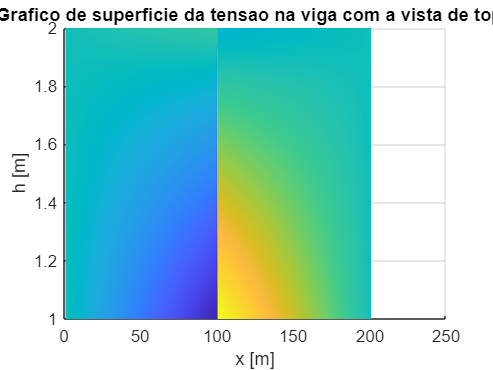

P = M0/L;
y = -(h/2):0.1:h/2;
x = 0:0.1:L;
Mz = momento(P,L,M0);
[Mz_mesh,y_mesh] = meshgrid(Mz,y);
Tensao = -(Mz_mesh.*y_mesh)/Izz;
surf(Tensao)
shading interp;
view(2)
ylabel('h [m]');
xlabel('x [m]');
title('Grafico de superficie da tensao na viga com a vista de topo');

Para criar o gráfico acima, utilizamos o metodo meshgrid com os parametros Mz e y para criar uma grade bidimensional com esses pontos. Com isso, utilizando a equacao dada para tensao na descricao do projeto definimos o nosso terceiro eixo para conseguirmos plotar o grafico. Por ultimo, utilizando a funçao view(2) deixamos o grafico representado numa vista 2D.

---------------------------------------------------------------------

Parte 2:

---------------------------------------------------------------------

L = 20;
E = 210e9; %Pa
Vy = @(P) (1/(E*Izz))*(((P*L)-M0)*((L.^2)/2)-((P*L.^3)/6)+(M0/2)*sing((L/2),2));
fplot(Vy,[0 (2*M0/L)]);
ylabel('Vy [m]');
xlabel('P [N]');%verificar unidade 
raiz = fzero(Vy,1250)

raiz = 1.4062e+03

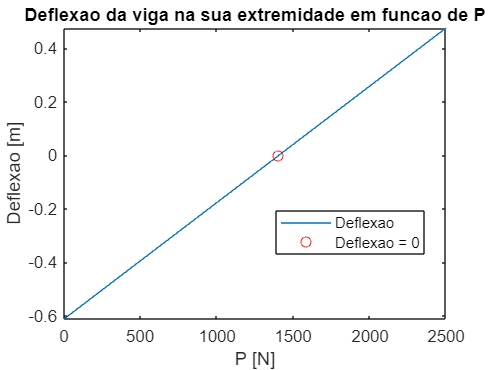

hold on
plot(raiz, 0, 'or')
ylabel('Deflexao [m]');
xlabel('P [N]');
legend('deflexao','deflexao nula','location','best')
title('Deflexao da viga na sua extremidade em funcao de P');
legend('Deflexao','Deflexao = 0','location','best')
hold off

Para conseguirmos plotar o grafico acima, substitui-se o valor de x por L, uma vez que é pedido a variaçao de Vy em funcao de P na extremidade da viga (x = L). Com isso plotamos o grafico para ter uma noçao inicial para que se possa estimar o valor da raiz. Com isso, Utilizamos o metodo fzero com o valor estimado, e conseguimos o valor exato da raiz da funçao pedida que é para P = 1406,3 N. Com isso, podemos observar que para valores de P entre 0 e menor que 1406,3 a deflexao é negativa, enquanto para valores maiores que essa raiz a deflexao é positiva. 

---------------------------------------------------------------------

Parte 3:

---------------------------------------------------------------------

P = M0/L;
Vy = @(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
fplot(Vy,[0 L]);
ylabel('Vy [m]');
xlabel('L [m]');
Vy_obtem_maximo = @(x) -1*(((1/(E*Izz))*(P*L-M0)*((x.^2)/(2))) - (P/6*E*Izz)*(x.^3)+(1/E*Izz)*(M0/2)*sing((x-(L/2)),2));
x_maxi = fminbnd(Vy_obtem_maximo,0,20)

x_maxi = 4.7187e-05

x_min = fminbnd(Vy,0,20)

x_min = 19.9999

Vy_maxi = Vy(x_maxi)

Vy_maxi = -3.5746e-18

Vy_min = Vy(x_min)

Vy_min = -0.0680

deflexao_zero = fzero(Vy, 0)

deflexao_zero = 0

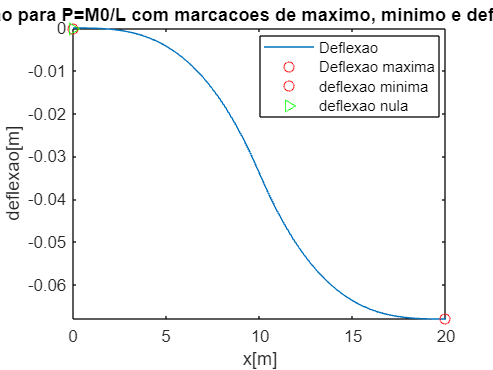

hold on
plot(x_maxi, Vy_maxi, 'or')
plot(x_min, Vy_min, 'or')
plot(0, deflexao_zero, '>g')
title('Deflexao para P=M0/L com marcacoes de maximo, minimo e deflexao zero');
xlabel('x[m]');
ylabel('deflexao[m]');
legend('Deflexao','Deflexao maxima','deflexao minima','deflexao nula','location','best');
hold off

Nessa parte do projeto esolhi a funcao de otimizaçao fminbnd devido a sua praticidade. Primeiro para poder estimar os valores maximos e minimos deve-se plotar o grafico da funçao para fazer essa analise. Para encontrarmos o valor exato de x minimo aplicamos a funcao fminbnd a funcao Vy estimando o valor de x. Para obter o valor exato de x maximo utilizamos a mesma funcao porem para a funcao -Vy. Agora, tendo os valores de x minimo e maximo basta fazermos Vy(x_min) e Vy(x_maxi) para obtermos Vy minimo e maximo. Para encontrarmos os pontos onde a deflexao é nula devemos utilizar a funcao Fzero de Vy. Por ultimo marcamos todos esses pontos no grafico.

---------------------------------------------------------------------

Parte 4:

---------------------------------------------------------------------

g = 9.81; %m/s^2
w0 = rho*b*h*g;
P = M0/L;

%[A]*[X] = [B], sendo [X] = [Ra Ma Rd]

Considerando w0:

%Considerando w0 
A = [L 1 0; 3*L/2 1 0; 1 0 1];
B1 = [(w0/2)*(L^2)-M0; w0*(((3*L/2)^2)/2)-M0-P*((3*L/2)-L); w0*((3*L)/2)-P];
X1 = A\B1;
Ra = X1(1, 1)

Ra = 1.9542e+04

Ma = X1(2, 1)

Ma = -2.4951e+05

Rd = X1(3, 1)

Rd = 4.1585e+03

Considerando w0 = 0:

%Considerando w0=0
w0 = 0; 
B2 = [(w0/2)*(L^2)-M0; w0*(((3*L/2)^2)/2)-M0-P*((3*L/2)-L) ; w0*((3*L)/2)-P];
X2 = A\B2;
Ra = X2(1, 1)

Ra = -1250

Ma = X2(2, 1)

Ma = 0

Rd = X2(3, 1)

Rd = 0

Somente a força P é aplicada:

%Somente a força P é aplicada
B3 = [0; P*((3*L/2)-L) ; -P];
X3 = A\B3;
Ra = X3(1, 1)

Ra = 1.2500e+03

Ma = X3(2, 1)

Ma = -2.5000e+04

Rd = X3(3, 1)

Rd = -2500

Somente o momento M0 é aplicado:

%Somente M0 é aplicado
B4 = [-M0; -M0 ; 0];
X4 = A\B4;
Ra = X4(1, 1)

Ra = 1.2127e-13

Ma = X4(2, 1)

Ma = -2.5000e+04

Rd = X4(3, 1)

Rd = -1.1369e-13

Nessa parte do projeto, desejamos encontrar 3 incognitas como é dito no enunciado, sendo elas Ra, Ma e Rd. Para isso nos temos 3 equacoes, tendo portanto um sistema determinado. 

Com isso, escolhi representar meu sistema na forma matricial na forma [A]*[X] = [B], sendo a matriz A aquela formada pelos fatores que multiplicam as incognitas, a matriz B formada pelos elemento que nao dependem de nenhuma das 3 incognitas, e a matriz X a matriz que fornece o resultado das 3 incognitas. 

Para encontrar a matriz x utilizei o metodo "\" fazendo A\B e armazenando o reesultado em X. Essa funcao facilita muito os calculos, uma vez que sao pedidos alguns casos diferentes dentro do problema, e seguindo essa logica bastou mudar o valor da matriz B para encontrar o novo resultado.

Para apresentar os dados eu optei por separar em topicos, sendo eles: Considerando w0 , considerando w0=0, somente a força P é aplicada, somente M0 é aplicado. Para expor o resultado acessei as posicoes na matriz e printei na dela o resultado de cada caso sendo Ra, Ma, Rd.

Segue as funçoes utilizadas no codigo:

function [d] = digitosRA(RA)
    
    % Funcao que retorna uma matriz d com cada
    % digito do RA escrito alocado em uma posicao
    % do vetor
    
    d = [];
    for i = 1:length(RA)
        numero = str2num(RA(i));
        d = [d numero];
    end
end

function [L,Izz,M0,b,h] = dados_problema(d)
    
    % Funcao que retorna todos os dados utilizados
    % nos exercicios seguintes

    if (d(5) == 0 && d(6) == 0)  
        L = 5;
    else
        L = 10*d(5) + d(6);
    end
    b = (10*d(3) + 2*d(4))*1e-2;
    h = 3*b;
    M0 = (10*d(1) + d(2))*1000;
    Izz=(b*(h^(3)))/12;
end

function y = sing(x,n)
    
    % singularity function y = <x-a>^n
    
    if n>=0
        y = x.^n.*(x>=0);
    else
        y = 0*x;
    end
end

function [Mz] = momento(P,L,M0)
   
   % Funcao que retorna o momento definido
   % por partes

   x = 0:0.1:L;
   l = length(x);
   Mz = 1:l;
   for i = 1:l
       if(i<(l/2))
           Mz(i) = P*L-M0-P*x(i);     
       end
       
       if(i>=(l/2))
           Mz(i) = P*(L-x(i));
       end
   end
end 